% NATURAL GAS PRICE QLD
% Wallumbilla Gas Supply Hub - trade volume and VWA prices by pipeline
% https://www.aer.gov.au/wholesale-markets/wholesale-statistics/wallumbilla-gas-supply-hub-trade-volume-and-vwa-prices-by-pipeline
% https://nemweb.com.au/Reports/Current/GSH/Benchmark_Price/

% RegionID = 'QLD1';
% bdate = datetime(2017,1,1); edate = datetime(2022,12,31);
% timespan = bdate:calmonths(1):edate;
% % Extract Gas-fired power data table. Gas (MW), RRP ($/MWh)
% CGdata = funcCoalGasdata(timespan,RegionID);

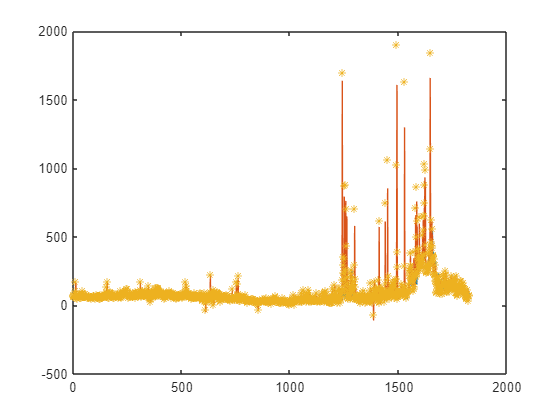

RRPdaily = median(reshape(CGdata.RRP,288,[]))';
[RRPdaily2,~,~] = funcAvrRRP(CGdata(:,{'SETTLEMENTDATE','RRP'}),start_date,end_date,288);
RRPdaily3 = totalGLdaily.genAUD./totalGLdaily.genMWh;
clf
plot(RRPdaily(397:end))
hold on
plot(RRPdaily2.AvrRRP,'-')
plot(RRPdaily3,'*')

NGasPrice = funcNGasPrice("NGasPrice.csv", [367, Inf])

NGasPrice = 1826×2 table
      NGDate      NGPrice
    __________    _______

    01/01/2018      7.9  
    02/01/2018      7.9  
    03/01/2018      7.9  
    04/01/2018     8.25  
    05/01/2018     8.25  
    06/01/2018     8.25  
    07/01/2018     8.25  
    08/01/2018     8.25  
    09/01/2018     8.25  
    10/01/2018     8.25  
    11/01/2018      8.3  
    12/01/2018     8.75  
    13/01/2018     9.31  
    14/01/2018     9.31  
    15/01/2018     9.31  
    16/01/2018     9.31  


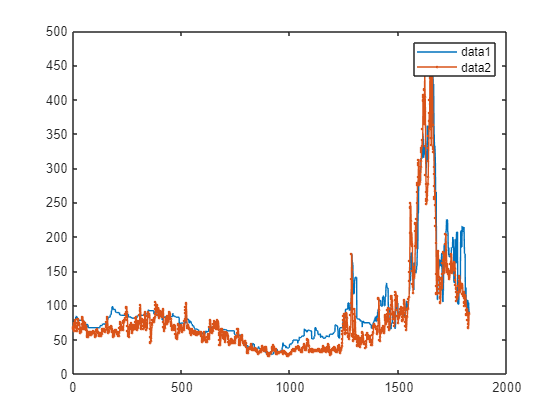

clf
mw = 14;
x = NGasPrice.NGPrice*9;
plot(x)
hold on
% plot(wavGasRRPdaily)
y = smooth(RRPdaily(397:end),5);
plot(y,'.-')
% ylim([0 500])
legend()

corr(x,y,type="Spearman")

ans = 0.8653

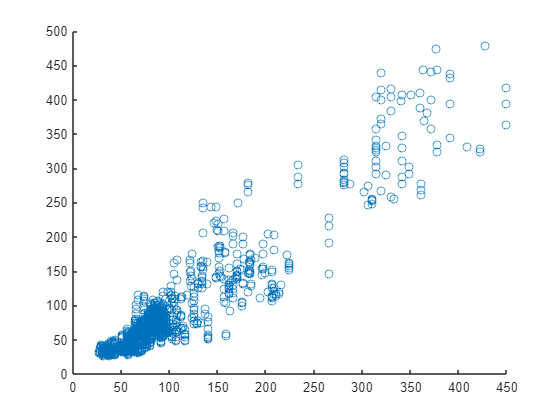

clf
scatter(x,y)